# Visualizing Climbing Sling Deformation

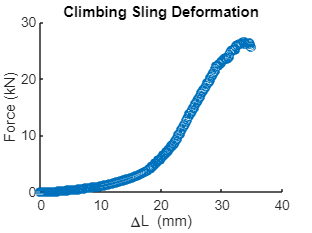

load("climbingSlingData.mat");
forceClimbing = forceClimbing./1000; % converting from N to kN
[denoisedPositionClimbing, denoisedForceClimbing] = smoothForceDisplacementData(positionClimbing, forceClimbing);
denoisedForceClimbing = denoisedForceClimbing - min(denoisedForceClimbing);
denoisedPositionClimbing = denoisedPositionClimbing - min(denoisedPositionClimbing);
figure
hold on
plot(denoisedPositionClimbing, denoisedForceClimbing, 'o')
title("Climbing Sling Deformation");
xlabel("\DeltaL (mm)")
ylabel("Force (kN)")

## Uncertainty Calculations

k = 2;
p = 0.005;
caliperUncertainty = (k.*p)./sqrt(6);
rigUncertainty = 0.17;
positionUncertainty = 1.026;
% Displacement and Force Uncertainty Calcs
displacementUncertainty = sqrt(positionUncertainty.^2 + ...
    rigUncertainty.^2 + caliperUncertainty.^2); % mm
forceUncertainty = 549.632./1000; % kN

## Locate the 3 Points of Interest, then Plot Uncertainty Bars

% Yield Strength: Index 293
% Ultimate Tensile Strength: Max Index
% Breaking Point Index: End Index
yieldStrengthIndex = 293

yieldStrengthIndex = 293

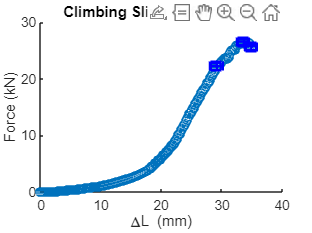

[~, ultTensileStrengthIndex] = max(denoisedForceClimbing);
pointsOfInterestIndices = [yieldStrengthIndex, ultTensileStrengthIndex, length(denoisedForceClimbing)];
% Error Bars for each POI
errorbar(denoisedPositionClimbing(pointsOfInterestIndices), ...
    denoisedForceClimbing(pointsOfInterestIndices), ...
    forceUncertainty, forceUncertainty, displacementUncertainty, ...
    displacementUncertainty, ...
    's', 'MarkerSize', 8, 'LineWidth', 1.5, 'Color', 'blue')

## For Each Point of Interest, Display Error Bounds (10%)

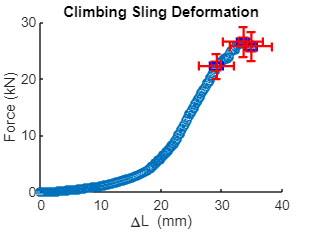

tenPercentForce = denoisedForceClimbing.* 0.10;
tenPercentPosition = denoisedPositionClimbing .* 0.10;
errorbar(denoisedPositionClimbing(pointsOfInterestIndices), ...
    denoisedForceClimbing(pointsOfInterestIndices), ...
    tenPercentForce(pointsOfInterestIndices), ...
    tenPercentForce(pointsOfInterestIndices), ...
    tenPercentPosition(pointsOfInterestIndices), ...
    tenPercentPosition(pointsOfInterestIndices), ...
    's', 'MarkerSize', 8, 'LineWidth', 1.5, 'Color', 'red')